=%13 practice
%Q1
func = @(t, y) -y + t^2;
y0 = 1

y0 =      1


range = 0:3;
h = 0.5;
accuracy = 0.1

accuracy =    0.100000000000000


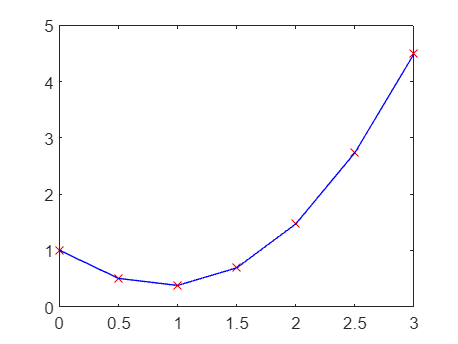

Ysolved = Euler(func, y0, range, h);
X = 0:0.5:3;
plot(X, Ysolved, 'rx');
hold on;
plot(X, Ysolved, '-b');
hold off;

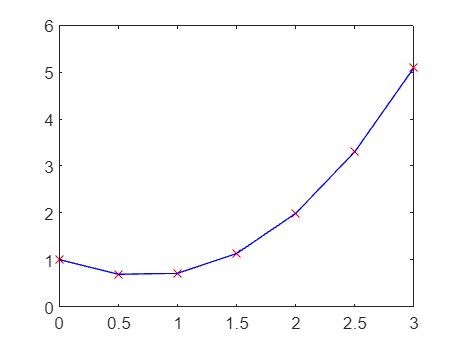

%Q2

YH = Heun(func, y0, range, h);
plot(X, YH, 'rx');
hold on;
plot(X, YH, '-b');
hold off;


%Q3
YHI = HeunIterativeMethod(func, 0, 3, y0, h, 0.1);

     5

     5

     5

     4

     4

     3



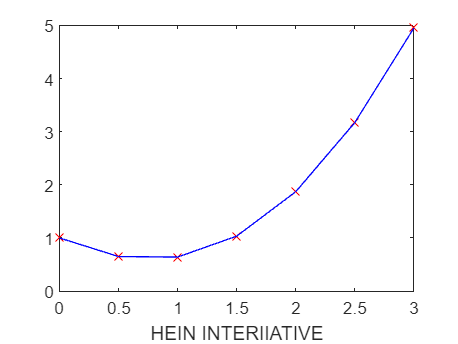

plot(X, YHI, 'rx');
xlabel(['HEIN INTERIIATIVE']);
hold on;
plot(X, YHI, '-b');
hold off;

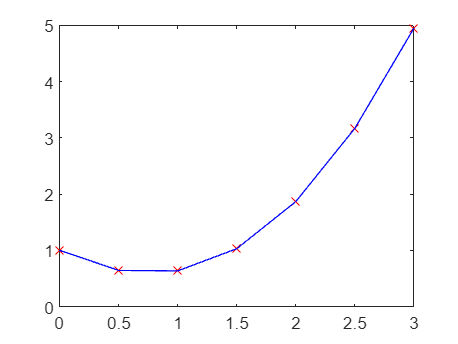



%Q4 plot with 4rk
[XRK4, YRK4] = RungeKuttaFourth(func, 0, 3, y0, h);
plot(XRK4, YRK4, 'rx');
hold on;
plot(XRK4, YRK4, '-b');
hold off;

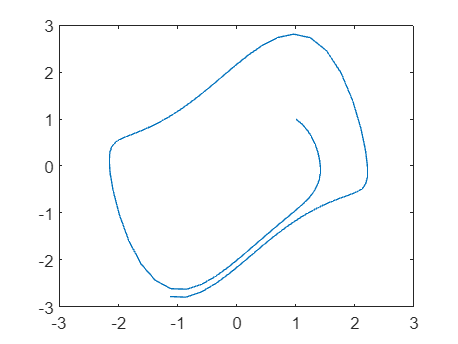

%% Practical Problems 13 Question 6
% Step 1: Setup
h = 0.1;
t = 0:h:10;
x1 = 1;
x2 = 1;
func1 = @(t,x1,x2) x2;
func2 = @(t,x1,x2) ((1 - x1.^2) .* x2) - x1;

for i = 1:length(t)-1
   x1(i+1) = x1(i) + h.*( func1(t(i) , x1(i) , x2(i)) ); %BASIC EULER
   x2(i+1) = x2(i) + h.*( func2(t(i) , x1(i) , x2(i)) ); %BASIC EULER
end
plot(x1,x2)   % Phase diagram of the 2 variables.

%Example
func = @(t, y) 4*exp( 0.8 * t ) - (0.5*y);
y0 = 2

y0 =      2


range = 0:4;
h = 1;
accuracy = 0.00001;
YH = Heun(func, y0, range, h);
Y = Euler(func, y0, range, h);
YHI = HeunIterativeMethod(func, 0, 4, y0, h, 0.00001);

    11

    11

    11

    11



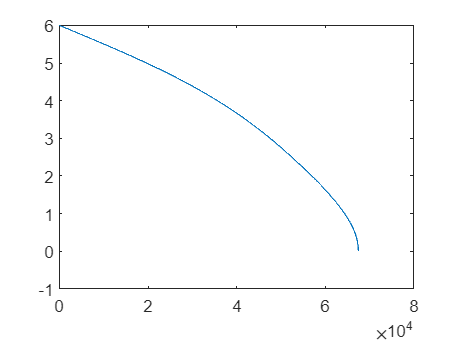

%% Practical Problems 13 Question 8
figure;
clear;
clc;
% Step 1: Setup
d = 0.25;
e = 1;
g = 9.81;

h = [6 5 4 3 2 1 0];
a = 10.^4 .* [1.17 0.97 0.67 0.45 0.32 0.18 0];

p = polyfit(h, a, 6);  % n-1
func = @(t, h) ( - (pi .* d.^2 ) ./ ( 4 .* ( polyval(p,h) ) )  .* (sqrt(2.*g.*(h+e))));

% Euler's to solve ODEs
i = 0;
hstep = 0.1;
t(1) = 0;
while 1
    i = i + 1;
    t(i+1) = t(i) + hstep;    % Increase time
    h(i+1) = h(i) + (func( t(i), h(i)) .* hstep);    % Use Euler's method or something else.
    if h(end) < 0 || imag(h(end)) > 0     % If the solution becomes negative or not real break the loop.
        break
    end
end
plot(t,h)

disp(['Time to drain is approximately t = ',num2str(t(end)),' seconds or ',num2str(t(end)/3600),' hours.'])

Time to drain is approximately t = 67455.4 seconds or 18.7376 hours.


function Y = Heun(func, y0, range, h)
     if length(range) == 1
        Y = y0;
    else
        Y(1) = y0;
        range = range(1):h:range(end);
        for i = 2:length(range)
            if i == 2
                 k1 = func(range(1), y0);
                 k2 = func(range(i - 1) + h, y0 + k1*h);
            else
                k1 = func(range(i - 1), Y(i - 1));
                k2 = func(range(i - 1) + h, Y(i - 1) + k1*h);
            end
            Ynext = Y(i - 1) + ((k1 + k2) / 2)*h;
            Y(end + 1) = Ynext;
        end
     end
end

function Y = Euler(func, y0, range, h)
    if length(range) == 1
        Y = y0;
    else
        Y(1) = y0;
        range = range(1):h:range(end);
        for i = 2:length(range)
            Ynext = Y(i - 1) + (h * func(range(i - 1), Y(i - 1)));
            Y(end + 1) = Ynext;
        end
    end
end

function y_array = HeunIterativeMethod(dy, start, final, init, step, tol)
    t = start:step:final;
    y_array = init;

    for j = 1:length(t) - 1
        init_slope = dy(t(j), y_array(j));
        init_next_y = y_array(j) + (init_slope * step);
        iter = 0;
        
        while iter < 100
            next_slope = dy(t(j) + step, init_next_y);
            avg_slope = (init_slope + next_slope) / 2;
            new_next_y = y_array(j) + (avg_slope * step);
            err = (abs((new_next_y - init_next_y) / new_next_y)) * 100;
            
            if err < tol
                y_array(end + 1) = new_next_y;
                break;
            else
                init_next_y = new_next_y;
                iter = iter + 1;
            end
        end
        disp(iter)
    end
end

 


function ans_array = EulerMethodOneOrder(dy, starttime, endtime, init, stepsize)
    ans_array = [init];
    t = starttime:stepsize:endtime;
    
    for count = t(2:end)
        ans_array = [ans_array, ans_array(end) + dy(count, ans_array(end)) * stepsize];
    end
    
    figure;
    subplot(2, 1, 1);
    plot(t, ans_array);
    title('Euler Method');
    
    subplot(2, 1, 2);
    plot(ans_array(1, :), ans_array(2, :));
    title('Phase Space');
end
